% Basically, we have to solve the three simultaneous ODEs.

syms v1(t) v2(t) v3(t) t

d1=diff(v1)==(v1-v2)/2-v3+5

$$d1(t) = \frac{\partial }{\partial t}v_{1}\left(t\right)=\frac{v_{1}\left(t\right)}{2}-\frac{v_{2}\left(t\right)}{2}-v_{3}\left(t\right)+5$$

d2=diff(v2)==v3-(v1-v2)/2-5

$$d2(t) = \frac{\partial }{\partial t}v_{2}\left(t\right)=\frac{v_{2}\left(t\right)}{2}-\frac{v_{1}\left(t\right)}{2}+v_{3}\left(t\right)-5$$

d3=diff(v3)==v1-v3+2

$$d3(t) = \frac{\partial }{\partial t}v_{3}\left(t\right)=v_{1}\left(t\right)-v_{3}\left(t\right)+2$$

de=[d1; d2; d3]

$$de(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}v_{1}\left(t\right)=\frac{v_{1}\left(t\right)}{2}-\frac{v_{2}\left(t\right)}{2}-v_{3}\left(t\right)+5\\ \frac{\partial }{\partial t}v_{2}\left(t\right)=\frac{v_{2}\left(t\right)}{2}-\frac{v_{1}\left(t\right)}{2}+v_{3}\left(t\right)-5\\ \frac{\partial }{\partial t}v_{3}\left(t\right)=v_{1}\left(t\right)-v_{3}\left(t\right)+2 \end{array}\right)$$

cond1=v1(0)==-3

$$cond1 = v_{1}\left(0\right)=-3$$

cond2=v2(0)==5

$$cond2 = v_{2}\left(0\right)=5$$

cond3=v3(0)==1

$$cond3 = v_{3}\left(0\right)=1$$

cond=[cond1; cond2; cond3]

$$cond = \left(\begin{array}{c} v_{1}\left(0\right)=-3\\ v_{2}\left(0\right)=5\\ v_{3}\left(0\right)=1 \end{array}\right)$$

s=dsolve(de, cond)

s = struct with fields:
    v2: (t*(3*t - 16))/2 - t - (t/2 - 1/2)*(6*t - 12) + t^2/2 + 11
    v1: t - (t*(3*t - 16))/2 + (t/2 - 1/2)*(6*t - 12) - t^2/2 - 9
    v3: 2*t - (t*(3*t - 16))/2 + (t/2 - 1)*(6*t - 12) - t^2/2 - 11


v1=s.v1

$$v1 = t-\frac{t\,\left(3\,t-16\right)}{2}+\left(\frac{t}{2}-\frac{1}{2}\right)\,\left(6\,t-12\right)-\frac{t^{2}}{2}-9$$

v2=s.v2

$$v2 = \frac{t\,\left(3\,t-16\right)}{2}-t-\left(\frac{t}{2}-\frac{1}{2}\right)\,\left(6\,t-12\right)+\frac{t^{2}}{2}+11$$

v3=s.v3

$$v3 = 2\,t-\frac{t\,\left(3\,t-16\right)}{2}+\left(\frac{t}{2}-1\right)\,\left(6\,t-12\right)-\frac{t^{2}}{2}-11$$

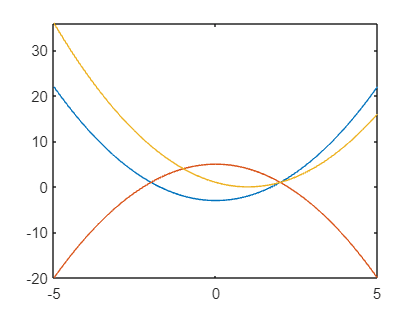

fplot(v1)
hold on
fplot(v2)
hold on 
fplot(v3)
hold off

syms Z real
z1=v1==Z

$$z1 = t-\frac{t\,\left(3\,t-16\right)}{2}+\left(\frac{t}{2}-\frac{1}{2}\right)\,\left(6\,t-12\right)-\frac{t^{2}}{2}-9=Z$$

z2=v2==Z

$$z2 = \frac{t\,\left(3\,t-16\right)}{2}-t-\left(\frac{t}{2}-\frac{1}{2}\right)\,\left(6\,t-12\right)+\frac{t^{2}}{2}+11=Z$$

z3=v3==Z

$$z3 = 2\,t-\frac{t\,\left(3\,t-16\right)}{2}+\left(\frac{t}{2}-1\right)\,\left(6\,t-12\right)-\frac{t^{2}}{2}-11=Z$$

sol=solve(z1,z2,z3)

sol = struct with fields:
    Z: 1
    t: 2


% Hence, at t=2 sec, v1==v2==v3==1 m/sec.
% So, the bomb can be diffused at t=2 sec.